# VisualRank Using Image Similarity

**1. Using the theory above, rank all 1400 MPEG7 shape images using VisualRank.**

**a. Load the sim.mat data file into MATLAB. This file contains the similarity matrix S  for the entire image dataset, as well as a cell array of corresponding filenames. **

load('sim.mat')  % retrive the variables from the binary file 'sim.mat' into similarity matrix S and cell array of corresponding filenames
disp(S) % display similarity matrix S

  Columns 1 through 8

    1.0000    0.9585    0.8079    0.7192    0.9924    0.8633    0.7679    0.8492
    0.9585    1.0000    0.7748    0.6916    0.9530    0.8842    0.7857    0.8392
    0.8079    0.7748    1.0000    0.8702    0.8082    0.7393    0.6907    0.7165
    0.7192    0.6916    0.8702    1.0000    0.7198    0.6704    0.6312    0.6448
    0.9924    0.9530    0.8082    0.7198    1.0000    0.8587    0.7664    0.8437
    0.8633    0.8842    0.7393    0.6704    0.8587    1.0000    0.8895    0.8407
    0.7679    0.7857    0.6907    0.6312    0.7664    0.8895    1.0000    0.8495
    0.8492    0.8392    0.7165    0.6448    0.8437    0.8407    0.8495    1.0000
    0.6913    0.6577    0.5592    0.4778    0.6863    0.6485    0.6284    0.7175
    0.5417    0.5257    0.7032    0.6266    0.5441    0.5676    0.6018    0.5473
    0.6161    0.5859    0.4553    0.3522    0.6121    0.5507    0.5344    0.5395
    0.9568    0.9157    0.8321    0.7541    0.9514    0.8364    0.7977    0.8688
    0

disp(filenames) % display corresponding filenames to the images in similarity matrix S

    'Bone-1.png'
    'Bone-10.png'
    'Bone-11.png'
    'Bone-12.png'
    'Bone-13.png'
    'Bone-14.png'
    'Bone-15.png'
    'Bone-16.png'
    'Bone-17.png'
    'Bone-18.png'
    'Bone-19.png'
    'Bone-2.png'
    'Bone-20.png'
    'Bone-3.png'
    'Bone-4.png'
    'Bone-5.png'
    'Bone-6.png'
    'Bone-7.png'
    'Bone-8.png'
    'Bone-9.png'
    'Comma-1.png'
    'Comma-10.png'
    'Comma-11.png'
    'Comma-12.png'
    'Comma-13.png'
    'Comma-14.png'
    'Comma-15.png'
    'Comma-16.png'
    'Comma-17.png'
    'Comma-18.png'
    'Comma-19.png'
    'Comma-2.png'
    'Comma-20.png'
    'Comma-3.png'
    'Comma-4.png'
    'Comma-5.png'
    'Comma-6.png'
    'Comma-7.png'
    'Comma-8.png'
    'Comma-9.png'
    'Glas-1.png'
    'Glas-10.png'
    'Glas-11.png'
    'Glas-12.png'
    'Glas-13.png'
    'Glas-14.png'
    'Glas-15.png'
    'Glas-16.png'
    'Glas-17.png'
    'Glas-18.png'
    'Glas-19.png'
    'Glas-2.png'
    'Glas-20.png'
    'Glas-3.png'
    'Glas-4.png'
    'Glas-5.

**b. Start by setting A=S, then remove elements from A to leave visual hyperlinks between only those images that are positively correlated. **

A = S % define adjacency matrix A

A =     1.0000    0.9585    0.8079    0.7192    0.9924    0.8633    0.7679    0.8492    0.6913    0.5417    0.6161    0.9568    0.6388    0.9847    0.9811    0.9737    0.9839    0.6893    0.6435    0.9646    0.1448    0.1311    0.2043    0.1586    0.1798    0.1231    0.1006    0.0975    0.1672    0.1261    0.1892    0.1688    0.1602    0.1007    0.1546    0.1348    0.2027    0.1721    0.0594    0.1800    0.1053    0.0867    0.1050    0.0857    0.1609    0.0713    0.1292    0.1021    0.1058    0.1044
    0.9585    1.0000    0.7748    0.6916    0.9530    0.8842    0.7857    0.8392    0.6577    0.5257    0.5859    0.9157    0.6222    0.9438    0.9412    0.9332    0.9425    0.6554    0.6108    0.9243    0.1702    0.1543    0.2242    0.1822    0.2067    0.1478    0.1036    0.1038    0.1907    0.1442    0.2135    0.1937    0.1876    0.1308    0.1773    0.1453    0.2297    0.2001    0.0880    0.2052    0.1151    0.0981    0.1146    0.0956    0.1700    0.0827    0.1431    0.1077    0.1155    0

A(A<0) = 0 % remove negative values from the matrix A

A =     1.0000    0.9585    0.8079    0.7192    0.9924    0.8633    0.7679    0.8492    0.6913    0.5417    0.6161    0.9568    0.6388    0.9847    0.9811    0.9737    0.9839    0.6893    0.6435    0.9646    0.1448    0.1311    0.2043    0.1586    0.1798    0.1231    0.1006    0.0975    0.1672    0.1261    0.1892    0.1688    0.1602    0.1007    0.1546    0.1348    0.2027    0.1721    0.0594    0.1800    0.1053    0.0867    0.1050    0.0857    0.1609    0.0713    0.1292    0.1021    0.1058    0.1044
    0.9585    1.0000    0.7748    0.6916    0.9530    0.8842    0.7857    0.8392    0.6577    0.5257    0.5859    0.9157    0.6222    0.9438    0.9412    0.9332    0.9425    0.6554    0.6108    0.9243    0.1702    0.1543    0.2242    0.1822    0.2067    0.1478    0.1036    0.1038    0.1907    0.1442    0.2135    0.1937    0.1876    0.1308    0.1773    0.1453    0.2297    0.2001    0.0880    0.2052    0.1151    0.0981    0.1146    0.0956    0.1700    0.0827    0.1431    0.1077    0.1155    0

**c. Finally, remove the elements from A that correspond to loop edges in the visual similarity graph. **

The diagonal elements of an adjacency matrix are typically zero, but a nonzero diagonal element indicates a self-loop, or a node that is connected to itself by an edge. Calling `diag` twice returns a diagonal matrix composed of the diagonal elements of the original matrix A.

A = A - diag(diag(A)) % remove the loop edges by subtracting diagonal elements of the original matrix A from matrix A 

A =          0    0.9585    0.8079    0.7192    0.9924    0.8633    0.7679    0.8492    0.6913    0.5417    0.6161    0.9568    0.6388    0.9847    0.9811    0.9737    0.9839    0.6893    0.6435    0.9646    0.1448    0.1311    0.2043    0.1586    0.1798    0.1231    0.1006    0.0975    0.1672    0.1261    0.1892    0.1688    0.1602    0.1007    0.1546    0.1348    0.2027    0.1721    0.0594    0.1800    0.1053    0.0867    0.1050    0.0857    0.1609    0.0713    0.1292    0.1021    0.1058    0.1044
    0.9585         0    0.7748    0.6916    0.9530    0.8842    0.7857    0.8392    0.6577    0.5257    0.5859    0.9157    0.6222    0.9438    0.9412    0.9332    0.9425    0.6554    0.6108    0.9243    0.1702    0.1543    0.2242    0.1822    0.2067    0.1478    0.1036    0.1038    0.1907    0.1442    0.2135    0.1937    0.1876    0.1308    0.1773    0.1453    0.2297    0.2001    0.0880    0.2052    0.1151    0.0981    0.1146    0.0956    0.1700    0.0827    0.1431    0.1077    0.1155    0

**d. Use A to create the hyperlink matrix H. **

Since each row of the adjacency matrix corresponds to one image, we can form the required matrix of link-following likelihoods by normalising each row so that they sum to 1.

H = normalize(A, 2, 'norm', 1) % construct hyperlink matrix H by normalising each row so that they sum to 1

H =          0    0.0121    0.0102    0.0091    0.0125    0.0109    0.0097    0.0107    0.0087    0.0068    0.0078    0.0121    0.0081    0.0124    0.0124    0.0123    0.0124    0.0087    0.0081    0.0122    0.0018    0.0017    0.0026    0.0020    0.0023    0.0016    0.0013    0.0012    0.0021    0.0016    0.0024    0.0021    0.0020    0.0013    0.0020    0.0017    0.0026    0.0022    0.0007    0.0023    0.0013    0.0011    0.0013    0.0011    0.0020    0.0009    0.0016    0.0013    0.0013    0.0013
    0.0123         0    0.0100    0.0089    0.0123    0.0114    0.0101    0.0108    0.0085    0.0068    0.0075    0.0118    0.0080    0.0122    0.0121    0.0120    0.0121    0.0084    0.0079    0.0119    0.0022    0.0020    0.0029    0.0023    0.0027    0.0019    0.0013    0.0013    0.0025    0.0019    0.0027    0.0025    0.0024    0.0017    0.0023    0.0019    0.0030    0.0026    0.0011    0.0026    0.0015    0.0013    0.0015    0.0012    0.0022    0.0011    0.0018    0.0014    0.0015    0

**e. Form the random jump matrix J. **

Adjacency matrix describes the connections between the nodes in the graph by the location of nonzero values. If node `i` and node `j` are connected, then `A(i,j)` or `A(j,i)` is nonzero; otherwise, `A(i,j)` and `A(j,i)` are zero.

H = ones(1400) is the adjacency matrix of a graph with 1400 nodes where each node is connected to all the others.

J = ones(size(H))/length(H) % create the jump matrix J

J = 	1.0e+-3 *

    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143
    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143   

**f. Given a damping factor of d = 0.85, create the modified visual hyperlink matrix Htilde. **

It has become standard to use 𝑑=0.85, in which case there is a 𝑑 = 0.85 =85% chance the user will select random images as usual and a (1−𝑑) = 0.15 =15% chance the user will get bored and jump to look for another images.

d = 0.85; % damping factor
Htilde = d*H + (1-d)*J % modified visual hyperlink matrix Htilde

Htilde =     0.0001    0.0104    0.0088    0.0078    0.0108    0.0094    0.0083    0.0092    0.0075    0.0059    0.0067    0.0104    0.0070    0.0107    0.0106    0.0106    0.0107    0.0075    0.0070    0.0105    0.0017    0.0015    0.0023    0.0018    0.0020    0.0014    0.0012    0.0012    0.0019    0.0015    0.0021    0.0019    0.0018    0.0012    0.0018    0.0016    0.0023    0.0020    0.0007    0.0020    0.0012    0.0010    0.0012    0.0010    0.0018    0.0009    0.0015    0.0012    0.0012    0.0012
    0.0106    0.0001    0.0086    0.0077    0.0105    0.0098    0.0087    0.0093    0.0073    0.0059    0.0065    0.0101    0.0069    0.0104    0.0104    0.0103    0.0104    0.0073    0.0068    0.0102    0.0020    0.0018    0.0026    0.0021    0.0024    0.0017    0.0012    0.0012    0.0022    0.0017    0.0024    0.0022    0.0022    0.0015    0.0020    0.0017    0.0026    0.0023    0.0011    0.0024    0.0014    0.0012    0.0014    0.0012    0.0020    0.0010    0.0017    0.0013    0.0014

**g. Find the VisualRank vector r using an initial vector creating the initial vector. **

r = zeros(1,length(A)); % intialize ranking vector
r(1,1) = 1; % add 1 as a place to start

nmax = 50; % iterate 50 times
for n=1:nmax
        r = r * Htilde
end

r =     0.0001    0.0104    0.0088    0.0078    0.0108    0.0094    0.0083    0.0092    0.0075    0.0059    0.0067    0.0104    0.0070    0.0107    0.0106    0.0106    0.0107    0.0075    0.0070    0.0105    0.0017    0.0015    0.0023    0.0018    0.0020    0.0014    0.0012    0.0012    0.0019    0.0015    0.0021    0.0019    0.0018    0.0012    0.0018    0.0016    0.0023    0.0020    0.0007    0.0020    0.0012    0.0010    0.0012    0.0010    0.0018    0.0009    0.0015    0.0012    0.0012    0.0012


r =     0.0019    0.0018    0.0017    0.0016    0.0018    0.0019    0.0018    0.0018    0.0015    0.0014    0.0012    0.0018    0.0015    0.0018    0.0018    0.0018    0.0018    0.0015    0.0014    0.0018    0.0009    0.0009    0.0011    0.0009    0.0010    0.0008    0.0008    0.0007    0.0010    0.0009    0.0010    0.0009    0.0010    0.0007    0.0009    0.0009    0.0012    0.0010    0.0007    0.0010    0.0006    0.0006    0.0006    0.0005    0.0006    0.0005    0.0006    0.0006    0.0006    0.0007


r =     0.5385    0.5314    0.5401    0.5681    0.5381    0.6130    0.6381    0.6040    0.4576    0.4815    0.3808    0.5640    0.5016    0.5415    0.5417    0.5397    0.5240    0.4573    0.4305    0.5430    0.7536    0.7679    0.9094    0.7407    0.7834    0.7085    0.6760    0.6410    0.7610    0.7887    0.7730    0.6859    0.7918    0.5996    0.6652    0.7570    0.8776    0.7980    0.6587    0.7738    0.3580    0.4053    0.3592    0.3273    0.3348    0.3037    0.3829    0.3462    0.3594    0.4538


r =     0.3082    0.3051    0.3326    0.3756    0.3074    0.3862    0.4208    0.3847    0.2754    0.3227    0.2266    0.3327    0.3258    0.3129    0.3124    0.3131    0.2971    0.2760    0.2613    0.3180    0.7236    0.7460    0.8671    0.7073    0.7366    0.6856    0.6578    0.6247    0.7253    0.7645    0.7299    0.6485    0.7564    0.5768    0.6298    0.7309    0.8202    0.7581    0.6527    0.7330    0.3054    0.3609    0.3067    0.2837    0.2743    0.2619    0.3277    0.2972    0.3068    0.4032


r =     0.2658    0.2635    0.2944    0.3400    0.2651    0.3440    0.3805    0.3443    0.2418    0.2935    0.1983    0.2903    0.2933    0.2710    0.2703    0.2715    0.2556    0.2427    0.2303    0.2768    0.7184    0.7424    0.8591    0.7013    0.7276    0.6819    0.6551    0.6218    0.7188    0.7603    0.7222    0.6424    0.7503    0.5727    0.6234    0.7268    0.8090    0.7506    0.6514    0.7257    0.2935    0.3507    0.2949    0.2738    0.2613    0.2523    0.3157    0.2865    0.2950    0.3918


r =     0.2578    0.2558    0.2873    0.3333    0.2572    0.3361    0.3729    0.3367    0.2355    0.2881    0.1930    0.2824    0.2872    0.2632    0.2625    0.2638    0.2478    0.2365    0.2245    0.2691    0.7175    0.7419    0.8575    0.7002    0.7259    0.6813    0.6548    0.6213    0.7177    0.7596    0.7209    0.6414    0.7493    0.5720    0.6223    0.7262    0.8068    0.7493    0.6511    0.7244    0.2910    0.3484    0.2924    0.2716    0.2586    0.2502    0.3132    0.2842    0.2925    0.3893


r =     0.2564    0.2543    0.2859    0.3321    0.2557    0.3346    0.3715    0.3353    0.2343    0.2871    0.1920    0.2809    0.2860    0.2617    0.2610    0.2623    0.2464    0.2353    0.2234    0.2676    0.7173    0.7418    0.8572    0.7000    0.7256    0.6812    0.6548    0.6212    0.7175    0.7595    0.7207    0.6413    0.7491    0.5718    0.6221    0.7261    0.8064    0.7490    0.6511    0.7242    0.2905    0.3480    0.2919    0.2711    0.2580    0.2498    0.3126    0.2838    0.2919    0.3888


r =     0.2561    0.2540    0.2857    0.3318    0.2555    0.3343    0.3712    0.3351    0.2341    0.2869    0.1919    0.2806    0.2858    0.2615    0.2607    0.2620    0.2461    0.2351    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7256    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7490    0.6511    0.7241    0.2904    0.3479    0.2918    0.2711    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3343    0.3712    0.3350    0.2340    0.2868    0.1918    0.2806    0.2858    0.2614    0.2606    0.2620    0.2460    0.2351    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595    0.7206    0.6413    0.7491    0.5718    0.6220    0.7261    0.8064    0.7489    0.6511    0.7241    0.2903    0.3478    0.2917    0.2710    0.2579    0.2497    0.3125    0.2837    0.2918    0.3887


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595


r =     0.2560    0.2540    0.2856    0.3318    0.2554    0.3342    0.3711    0.3350    0.2340    0.2868    0.1918    0.2805    0.2858    0.2614    0.2606    0.2620    0.2460    0.2350    0.2232    0.2673    0.7173    0.7418    0.8572    0.7000    0.7255    0.6812    0.6548    0.6212    0.7174    0.7595


**h. Given this VisualRank vector, which image is ranked highest? Display this image. **

[~,rank] = sort(r,'descend') % rank and sort in descending order

rank =          713         714         719         701         704         705         561         564         580         552         593         583         587         592         708        1003         581         588         594         718        1123         653         647         582         657         578         566         715         563         579


highest_ranked_image = rank(1) % determine highest ranked image 

highest_ranked_image = 713

filenames_h = filenames(highest_ranked_image,1) % extract filenames for the corresponding highest ranked image

filenames_h = 1×1 cell array
    {'device9-20.png'}


C = convertCharsToStrings(filenames_h) % converts characters to strings

C = "device9-20.png"

figure % plot the highest ranked image
img_1 = imread(sprintf("./MPEG7/%s", C))

img_1 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

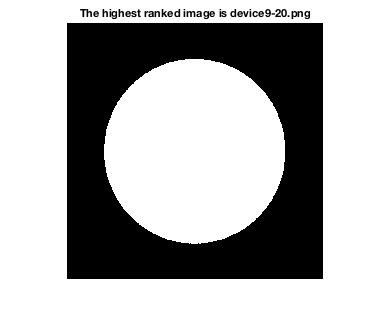

imshow(img_1)
title(sprintf("The highest ranked image is %s", C))

VisualRank ranks images in a group by how representative they are of the group as a whole. This is a difficult task when the group of images is large and varied, as it is in this case. T

he only common feature among all 1400 images is that the images tend to depict some white object toward the centre of the frame, as can be seen by the average of all the images:

                        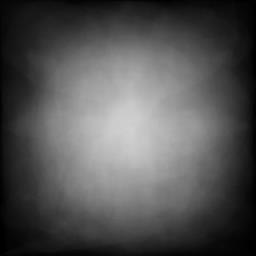

Thus, if you have answered everything above correctly, you should have found a #1 image that looks very vaguely like this.

In practice, VisualRank is much more usefully applied to smaller groups of similar or related images, as is the focus of the following tasks.

**2. Rank the 20 heart-shaped images (indices 81 through 100) using VisualRank.**

**a. Make a smaller 20x20 adjacency matrix by indexing the necessary rows andcolumns of the full adjacency matrix from above. **

A = S; % define adjacency matrix A
As = A(81:100,81:100) % create a smaller adjacency matrix As

As =     1.0000    0.8476    0.9673    0.8830    0.9497    0.9948    0.9257    0.8508    0.9506    0.8991    0.9327    0.8640    0.7887    0.9667    0.9471    0.7971    0.9597    0.9386    0.8701    0.8347
    0.8476    1.0000    0.8164    0.7820    0.8006    0.8474    0.8417    0.7744    0.8729    0.7496    0.7991    0.7471    0.8273    0.8362    0.8188    0.6859    0.8140    0.8189    0.7970    0.6982
    0.9673    0.8164    1.0000    0.8730    0.9175    0.9629    0.8926    0.8161    0.9182    0.9293    0.9002    0.8419    0.7567    0.9351    0.9161    0.7805    0.9273    0.9065    0.8386    0.8264
    0.8830    0.7820    0.8730    1.0000    0.8346    0.8823    0.8133    0.7389    0.8376    0.8140    0.8761    0.7640    0.7626    0.8539    0.8360    0.7302    0.8665    0.8503    0.7928    0.7416
    0.9497    0.8006    0.9175    0.8346    1.0000    0.9454    0.8745    0.8464    0.9000    0.9467    0.8818    0.8199    0.7404    0.9181    0.8994    0.7544    0.9099    0.8893    0.8278 

As(As<0) = 0 % remove negative values from the matrix A

As =     1.0000    0.8476    0.9673    0.8830    0.9497    0.9948    0.9257    0.8508    0.9506    0.8991    0.9327    0.8640    0.7887    0.9667    0.9471    0.7971    0.9597    0.9386    0.8701    0.8347
    0.8476    1.0000    0.8164    0.7820    0.8006    0.8474    0.8417    0.7744    0.8729    0.7496    0.7991    0.7471    0.8273    0.8362    0.8188    0.6859    0.8140    0.8189    0.7970    0.6982
    0.9673    0.8164    1.0000    0.8730    0.9175    0.9629    0.8926    0.8161    0.9182    0.9293    0.9002    0.8419    0.7567    0.9351    0.9161    0.7805    0.9273    0.9065    0.8386    0.8264
    0.8830    0.7820    0.8730    1.0000    0.8346    0.8823    0.8133    0.7389    0.8376    0.8140    0.8761    0.7640    0.7626    0.8539    0.8360    0.7302    0.8665    0.8503    0.7928    0.7416
    0.9497    0.8006    0.9175    0.8346    1.0000    0.9454    0.8745    0.8464    0.9000    0.9467    0.8818    0.8199    0.7404    0.9181    0.8994    0.7544    0.9099    0.8893    0.8278 

As = As - diag(diag(As)) % remove the loop edges by subtracting diagonal elements of the original matrix A from matrix A 

As =          0    0.8476    0.9673    0.8830    0.9497    0.9948    0.9257    0.8508    0.9506    0.8991    0.9327    0.8640    0.7887    0.9667    0.9471    0.7971    0.9597    0.9386    0.8701    0.8347
    0.8476         0    0.8164    0.7820    0.8006    0.8474    0.8417    0.7744    0.8729    0.7496    0.7991    0.7471    0.8273    0.8362    0.8188    0.6859    0.8140    0.8189    0.7970    0.6982
    0.9673    0.8164         0    0.8730    0.9175    0.9629    0.8926    0.8161    0.9182    0.9293    0.9002    0.8419    0.7567    0.9351    0.9161    0.7805    0.9273    0.9065    0.8386    0.8264
    0.8830    0.7820    0.8730         0    0.8346    0.8823    0.8133    0.7389    0.8376    0.8140    0.8761    0.7640    0.7626    0.8539    0.8360    0.7302    0.8665    0.8503    0.7928    0.7416
    0.9497    0.8006    0.9175    0.8346         0    0.9454    0.8745    0.8464    0.9000    0.9467    0.8818    0.8199    0.7404    0.9181    0.8994    0.7544    0.9099    0.8893    0.8278 

**b. Form the corresponding visual hyperlink matrix and find the VisualRank vector for all 20 heart images. **

Hs = normalize(As, 2, 'norm', 1) % construct the corresponding hyperlink matrix Hs 

Hs =          0    0.0494    0.0563    0.0514    0.0553    0.0579    0.0539    0.0496    0.0554    0.0524    0.0543    0.0503    0.0459    0.0563    0.0552    0.0464    0.0559    0.0547    0.0507    0.0486
    0.0559         0    0.0538    0.0515    0.0528    0.0558    0.0555    0.0510    0.0575    0.0494    0.0527    0.0492    0.0545    0.0551    0.0540    0.0452    0.0536    0.0540    0.0525    0.0460
    0.0578    0.0488         0    0.0522    0.0549    0.0576    0.0534    0.0488    0.0549    0.0556    0.0538    0.0503    0.0452    0.0559    0.0548    0.0467    0.0555    0.0542    0.0501    0.0494
    0.0568    0.0503    0.0562         0    0.0537    0.0568    0.0524    0.0476    0.0539    0.0524    0.0564    0.0492    0.0491    0.0550    0.0538    0.0470    0.0558    0.0547    0.0510    0.0477
    0.0578    0.0487    0.0558    0.0508         0    0.0575    0.0532    0.0515    0.0547    0.0576    0.0536    0.0499    0.0450    0.0558    0.0547    0.0459    0.0553    0.0541    0.0503 

Js = ones(size(Hs))/length(Hs) % create the jump matrix Js

Js =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500 

d = 0.85 % damping factor

d = 0.8500


Htildes = (d*Hs) + (1 - d)*Js % create the modified hyperlink matrix Htildes

Htildes =     0.0075    0.0495    0.0554    0.0512    0.0545    0.0568    0.0533    0.0496    0.0546    0.0520    0.0537    0.0503    0.0466    0.0554    0.0544    0.0470    0.0550    0.0540    0.0506    0.0488
    0.0550    0.0075    0.0532    0.0513    0.0523    0.0550    0.0546    0.0509    0.0564    0.0495    0.0523    0.0493    0.0538    0.0543    0.0534    0.0459    0.0531    0.0534    0.0521    0.0466
    0.0567    0.0490    0.0075    0.0519    0.0541    0.0564    0.0529    0.0490    0.0542    0.0547    0.0533    0.0503    0.0460    0.0550    0.0541    0.0472    0.0546    0.0536    0.0501    0.0495
    0.0558    0.0503    0.0553    0.0075    0.0532    0.0558    0.0520    0.0479    0.0533    0.0520    0.0554    0.0493    0.0492    0.0542    0.0532    0.0475    0.0549    0.0540    0.0509    0.0481
    0.0566    0.0489    0.0549    0.0506    0.0075    0.0564    0.0527    0.0513    0.0540    0.0564    0.0531    0.0499    0.0458    0.0550    0.0540    0.0465    0.0545    0.0535    0.

rs = zeros(1,20) % initialise ranking vector

rs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


rs(1,1)=1 % add 1 as a place to start

rs =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


nmax = 5 % iterate 5 times 

nmax = 5

for n=1:nmax
        rs = rs * Htildes
end

rs =     0.0075    0.0495    0.0554    0.0512    0.0545    0.0568    0.0533    0.0496    0.0546    0.0520    0.0537    0.0503    0.0466    0.0554    0.0544    0.0470    0.0550    0.0540    0.0506    0.0488


rs =     0.0556    0.0480    0.0520    0.0488    0.0512    0.0530    0.0504    0.0472    0.0513    0.0492    0.0509    0.0487    0.0453    0.0523    0.0514    0.0456    0.0520    0.0513    0.0489    0.0469


rs =     0.0532    0.0480    0.0522    0.0490    0.0514    0.0532    0.0506    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


rs =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0521    0.0514    0.0489    0.0470


rs =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


[~,rank] = sort(rs,'descend') % rank and sort in descending order values of VisualRank vector rs

rank =      1     6    14    17     3    15     9    18     5    11     7    10     4    19    12     2     8    20    16    13


filenames_s = filenames(81:100) % extract filenames for the corresponding images

filenames_s = 20×1 cell array
    {'Heart-1.png' }
    {'Heart-10.png'}
    {'Heart-11.png'}
    {'Heart-12.png'}
    {'Heart-13.png'}
    {'Heart-14.png'}
    {'Heart-15.png'}
    {'Heart-16.png'}
    {'Heart-17.png'}
    {'Heart-18.png'}
    {'Heart-19.png'}
    {'Heart-2.png' }
    {'Heart-20.png'}
    {'Heart-3.png' }
    {'Heart-4.png' }
    {'Heart-5.png' }
    {'Heart-6.png' }
    {'Heart-7.png' }
    {'Heart-8.png' }
    {'Heart-9.png' }


**c. Given this ranking, which heart-shaped image is most representative of the group of heart-shaped images? Display this image. **

most = rank(1); % most representative heart-shaped image according to VisualRank
disp('The most representative heart shaped image is: '), filenames_s(most,1) % display this image

The most representative heart shaped image is: 


ans = 1×1 cell array
    {'Heart-1.png'}


C1 = convertCharsToStrings(filenames_s) % convert characters to strings

C1 = 20×1 string array
    "Heart-1.png"
    "Heart-10.png"
    "Heart-11.png"
    "Heart-12.png"
    "Heart-13.png"
    "Heart-14.png"
    "Heart-15.png"
    "Heart-16.png"
    "Heart-17.png"
    "Heart-18.png"
    "Heart-19.png"
    "Heart-2.png"
    "Heart-20.png"
    "Heart-3.png"
    "Heart-4.png"
    "Heart-5.png"
    "Heart-6.png"
    "Heart-7.png"
    "Heart-8.png"
    "Heart-9.png"


figure % plot the most representative image
img_2 = imread(sprintf("./MPEG7/%s", C1(most,1)))

img_2 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

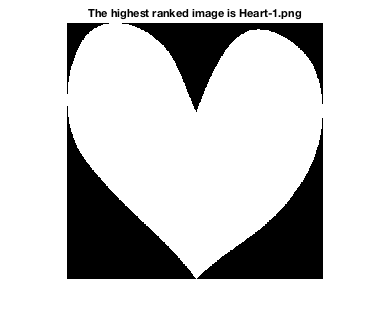

imshow(img_2)
title(sprintf("The highest ranked image is %s", C1(most,1)))

**d. Similarly, which heart-shaped image is the least heart-shaped (according toVisualRank)? Also display this image. (1 mark)**

least = rank(20) % least heart-shaped image according to VisualRank 

least = 13

disp('The least heart shaped image is: '), filenames_s(least,1) % display this image

The least heart shaped image is: 


ans = 1×1 cell array
    {'Heart-20.png'}


figure % plot the least heart-shaped image
img_3 = imread(sprintf("./MPEG7/%s", C1(least,1)))

img_3 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

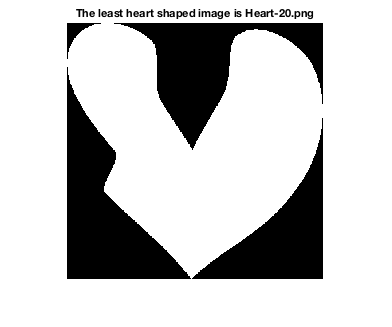

imshow(img_3);
title(sprintf("The least heart shaped image is %s", C1(least,1)))

**3. Pretend you are a search engine that has been queried for an image search of thefollowing pentagon-looking shape that is present in the dataset as ‘device6-18.png’(at index 650):**

                      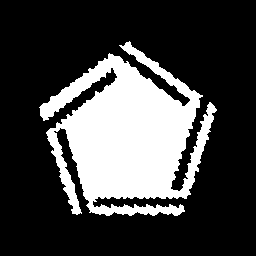

MATLAB has a nearest function that finds the nearest nodes to a particular node on a graph. We will use this function to search for the images similar (near) to the image above and then refine these search results using VisualRank.

**a. We first need to create a graph from the similarity adjacency matrix A created in Task 1. However, we cannot use this matrix directly, as it contains edge weights that are larger when images are more similar, corresponding to a further distance. We would instead like images that are similar to each other to be nearer in the graph. This can be achieved simply forming a new adjacency matrix for which the elements are the reciprocal of those in A. Do this, and, using the digraph function, form the graph G corresponding to this new adjacency matrix. **

A = S % define adjacency matrix A

A =     1.0000    0.9585    0.8079    0.7192    0.9924    0.8633    0.7679    0.8492    0.6913    0.5417    0.6161    0.9568    0.6388    0.9847    0.9811    0.9737    0.9839    0.6893    0.6435    0.9646    0.1448    0.1311    0.2043    0.1586    0.1798    0.1231    0.1006    0.0975    0.1672    0.1261
    0.9585    1.0000    0.7748    0.6916    0.9530    0.8842    0.7857    0.8392    0.6577    0.5257    0.5859    0.9157    0.6222    0.9438    0.9412    0.9332    0.9425    0.6554    0.6108    0.9243    0.1702    0.1543    0.2242    0.1822    0.2067    0.1478    0.1036    0.1038    0.1907    0.1442
    0.8079    0.7748    1.0000    0.8702    0.8082    0.7393    0.6907    0.7165    0.5592    0.7032    0.4553    0.8321    0.6659    0.7920    0.8176    0.7957    0.7942    0.5045    0.5675    0.7663    0.1548    0.1446    0.2016    0.1453    0.1876    0.1346    0.1355    0.0979    0.1513    0.1711
    0.7192    0.6916    0.8702    1.0000    0.7198    0.6704    0.6312    0.6448    0.4778   

A(A<0) = 0 % remove negative values from the matrix A

A =     1.0000    0.9585    0.8079    0.7192    0.9924    0.8633    0.7679    0.8492    0.6913    0.5417    0.6161    0.9568    0.6388    0.9847    0.9811    0.9737    0.9839    0.6893    0.6435    0.9646    0.1448    0.1311    0.2043    0.1586    0.1798    0.1231    0.1006    0.0975    0.1672    0.1261
    0.9585    1.0000    0.7748    0.6916    0.9530    0.8842    0.7857    0.8392    0.6577    0.5257    0.5859    0.9157    0.6222    0.9438    0.9412    0.9332    0.9425    0.6554    0.6108    0.9243    0.1702    0.1543    0.2242    0.1822    0.2067    0.1478    0.1036    0.1038    0.1907    0.1442
    0.8079    0.7748    1.0000    0.8702    0.8082    0.7393    0.6907    0.7165    0.5592    0.7032    0.4553    0.8321    0.6659    0.7920    0.8176    0.7957    0.7942    0.5045    0.5675    0.7663    0.1548    0.1446    0.2016    0.1453    0.1876    0.1346    0.1355    0.0979    0.1513    0.1711
    0.7192    0.6916    0.8702    1.0000    0.7198    0.6704    0.6312    0.6448    0.4778   

A = A - diag(diag(A)) % remove the loop edges by subtracting diagonal elements of the original matrix A from matrix A 

A =          0    0.9585    0.8079    0.7192    0.9924    0.8633    0.7679    0.8492    0.6913    0.5417    0.6161    0.9568    0.6388    0.9847    0.9811    0.9737    0.9839    0.6893    0.6435    0.9646    0.1448    0.1311    0.2043    0.1586    0.1798    0.1231    0.1006    0.0975    0.1672    0.1261
    0.9585         0    0.7748    0.6916    0.9530    0.8842    0.7857    0.8392    0.6577    0.5257    0.5859    0.9157    0.6222    0.9438    0.9412    0.9332    0.9425    0.6554    0.6108    0.9243    0.1702    0.1543    0.2242    0.1822    0.2067    0.1478    0.1036    0.1038    0.1907    0.1442
    0.8079    0.7748         0    0.8702    0.8082    0.7393    0.6907    0.7165    0.5592    0.7032    0.4553    0.8321    0.6659    0.7920    0.8176    0.7957    0.7942    0.5045    0.5675    0.7663    0.1548    0.1446    0.2016    0.1453    0.1876    0.1346    0.1355    0.0979    0.1513    0.1711
    0.7192    0.6916    0.8702         0    0.7198    0.6704    0.6312    0.6448    0.4778   

Arec = 1./A % find reciprocal of A

Arec =        Inf    1.0433    1.2378    1.3904    1.0077    1.1583    1.3022    1.1775    1.4465    1.8461    1.6230    1.0451    1.5654    1.0155    1.0192    1.0270    1.0164    1.4507    1.5541    1.0367    6.9077    7.6259    4.8946    6.3065    5.5613    8.1230    9.9362   10.2551    5.9820    7.9313
    1.0433       Inf    1.2907    1.4460    1.0494    1.1309    1.2728    1.1916    1.5204    1.9021    1.7068    1.0921    1.6072    1.0595    1.0625    1.0716    1.0610    1.5258    1.6371    1.0818    5.8737    6.4827    4.4609    5.4885    4.8388    6.7657    9.6515    9.6359    5.2447    6.9342
    1.2378    1.2907       Inf    1.1491    1.2374    1.3527    1.4477    1.3956    1.7884    1.4220    2.1964    1.2018    1.5018    1.2626    1.2231    1.2567    1.2591    1.9820    1.7621    1.3050    6.4594    6.9177    4.9606    6.8826    5.3297    7.4299    7.3785   10.2187    6.6074    5.8451
    1.3904    1.4460    1.1491       Inf    1.3893    1.4916    1.5842    1.5509    2.0929

G = digraph(Arec, filenames) % Generate  a new adjacency matrix for which the elements are  reciprocal of those in A by using digraph

G =   digraph with properties:

    Edges: [1960000×2 table]
    Nodes: [1400×1 table]


G.Edges % view the edge list of the graph

ans = 1960000×2 table
                EndNodes                 Weight
    _________________________________    ______

    {'Bone-1.png'}    {'Bone-1.png' }       Inf
    {'Bone-1.png'}    {'Bone-10.png'}    1.0433
    {'Bone-1.png'}    {'Bone-11.png'}    1.2378
    {'Bone-1.png'}    {'Bone-12.png'}    1.3904
    {'Bone-1.png'}    {'Bone-13.png'}    1.0077
    {'Bone-1.png'}    {'Bone-14.png'}    1.1583
    {'Bone-1.png'}    {'Bone-15.png'}    1.3022
    {'Bone-1.png'}    {'Bone-16.png'}    1.1775
    {'Bone-1.png'}    {'Bone-17.png'}    1.4465
    {'Bone-1.png'}    {'Bone-18.png'}    1.8461
    {'Bone-1.png'}    {'Bone-19.png'}     1.623
    {'Bone-1.png'}    {'Bone-2.png' }    1.0451
    {'Bone-1.png'}    {'Bone-20.png'}    1.5654
    {'Bone-1.png'}    {'Bone-3.png' }    1.0155
    {'Bone-1.png'}    {'Bone-4.png' }    1.0192
    {'Bone-1.png'}    {'Bone-5.png' }     1.027


G = rmedge(G, 1:numnodes(G), 1:numnodes(G)) % remove all self-loops from the graph

G =   digraph with properties:

    Edges: [1958600×2 table]
    Nodes: [1400×1 table]


   **b. Using MATLAB’s nearest function, find the 10 images nearest to ‘device6-18.png’ in the graph G. **

Index number of the ‘device6-18.png’ image is 650 in the filenames

[NODEISD, DIST]  = nearest(G,650,10) % determine which nodes are in a radius of 10 from node 650

NODEISD =    645
   654
   657
   647
   653
   649
   644
   643
   655
   656


DIST =     1.0447
    1.2318
    1.2765
    1.2847
    1.2869
    1.3032
    1.3215
    1.3622
    1.3656
    1.3747


Ten_nearest = NODEISD((1:10),1) % determine the ten nearest nodes

Ten_nearest =    645
   654
   657
   647
   653
   649
   644
   643
   655
   656


filenames_t = filenames(Ten_nearest) % extract filenames for the corresponding images

filenames_t = 10×1 cell array
    {'device6-13.png'}
    {'device6-3.png' }
    {'device6-6.png' }
    {'device6-15.png'}
    {'device6-20.png'}
    {'device6-17.png'}
    {'device6-12.png'}
    {'device6-11.png'}
    {'device6-4.png' }
    {'device6-5.png' }



disp ('The 10 nearest images are: '),filenames_t % display the filenames of the corresponding images

The 10 nearest images are: 


filenames_t = 10×1 cell array
    {'device6-13.png'}
    {'device6-3.png' }
    {'device6-6.png' }
    {'device6-15.png'}
    {'device6-20.png'}
    {'device6-17.png'}
    {'device6-12.png'}
    {'device6-11.png'}
    {'device6-4.png' }
    {'device6-5.png' }


% assigning values to x and y axes to form a bar plot
x = categorical({'device6-13','device6-3', 'device6-6', 'device6-15', 'device6-20', 'device6-17', 'device6-12', 'device6-11', 'device6-4', 'device6-5'}); 
x = reordercats(x,{'device6-13','device6-3', 'device6-6', 'device6-15', 'device6-20', 'device6-17', 'device6-12', 'device6-11', 'device6-4', 'device6-5'}); 
y = Ten_nearest

y =    645
   654
   657
   647
   653
   649
   644
   643
   655
   656



figure % bar plot the ten nearest images
     b = bar(x,y, 'm', 'EdgeColor', 'c', 'LineWidth', 1)

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [1 0 1]
    EdgeColor: [0 1 1]
    BaseValue: 0
        XData: [device6-13    device6-3    device6-6    device6-15    device6-20    device6-17    device6-12    device6-11    device6-4    device6-5]
        YData: [645 654 657 647 653 649 644 643 655 656]

  Show all properties


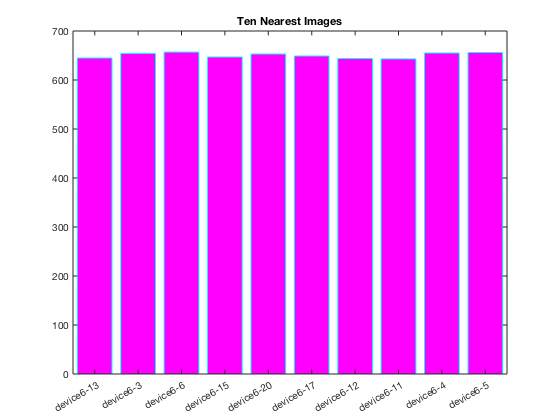

     title('Ten Nearest Images')


C3 = convertCharsToStrings(filenames_t)

C3 = 10×1 string array
    "device6-13.png"
    "device6-3.png"
    "device6-6.png"
    "device6-15.png"
    "device6-20.png"
    "device6-17.png"
    "device6-12.png"
    "device6-11.png"
    "device6-4.png"
    "device6-5.png"


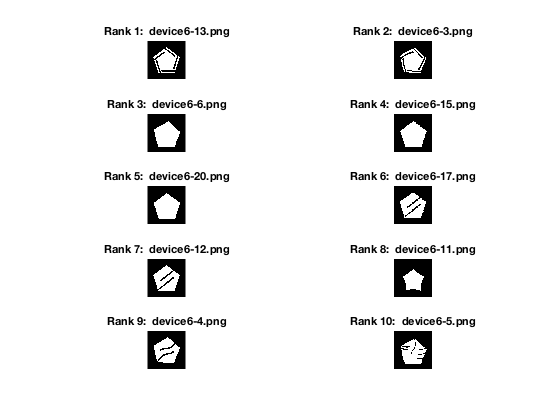

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

im_4 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

figure; % plot the ten nearest images according to nearest function
for i = 1:10
subplot(5,2,i)
im_4 = imread(sprintf("./MPEG7/%s", C3(i, 1)))
imshow(im_4)
title(sprintf("Rank %d:  %s",i, C3(i,1)))
end

**c. Finally, rank these 10 nearest images using VisualRank and display them on a figure in their ranked order. This is the final search result. **

A = S % define matrix A

A =     1.0000    0.9585    0.8079    0.7192    0.9924    0.8633    0.7679    0.8492    0.6913    0.5417    0.6161    0.9568    0.6388    0.9847    0.9811    0.9737    0.9839    0.6893    0.6435    0.9646    0.1448    0.1311    0.2043    0.1586    0.1798    0.1231    0.1006    0.0975    0.1672    0.1261
    0.9585    1.0000    0.7748    0.6916    0.9530    0.8842    0.7857    0.8392    0.6577    0.5257    0.5859    0.9157    0.6222    0.9438    0.9412    0.9332    0.9425    0.6554    0.6108    0.9243    0.1702    0.1543    0.2242    0.1822    0.2067    0.1478    0.1036    0.1038    0.1907    0.1442
    0.8079    0.7748    1.0000    0.8702    0.8082    0.7393    0.6907    0.7165    0.5592    0.7032    0.4553    0.8321    0.6659    0.7920    0.8176    0.7957    0.7942    0.5045    0.5675    0.7663    0.1548    0.1446    0.2016    0.1453    0.1876    0.1346    0.1355    0.0979    0.1513    0.1711
    0.7192    0.6916    0.8702    1.0000    0.7198    0.6704    0.6312    0.6448    0.4778   

At = A([643 644 645 647 649 653 654 655 656 657],[643 644 645 647 649 653 654 655 656 657]) % create a small adjacency matrix for those 10 images

At =     1.0000    0.6203    0.7309    0.7280    0.6187    0.7274    0.7223    0.6232    0.6768    0.7279
    0.6203    1.0000    0.7697    0.8299    0.9710    0.8287    0.7257    0.8128    0.7607    0.8297
    0.7309    0.7697    1.0000    0.7752    0.7566    0.7756    0.8149    0.7348    0.7255    0.7821
    0.7280    0.8299    0.7752    1.0000    0.8314    0.9859    0.7625    0.8223    0.8852    0.9524
    0.6187    0.9710    0.7566    0.8314    1.0000    0.8299    0.7225    0.8114    0.7625    0.8307
    0.7274    0.8287    0.7756    0.9859    0.8299    1.0000    0.7626    0.8221    0.8874    0.9545
    0.7223    0.7257    0.8149    0.7625    0.7225    0.7626    1.0000    0.7717    0.7206    0.7783
    0.6232    0.8128    0.7348    0.8223    0.8114    0.8221    0.7717    1.0000    0.7641    0.8314
    0.6768    0.7607    0.7255    0.8852    0.7625    0.8874    0.7206    0.7641    1.0000    0.9306
    0.7279    0.8297    0.7821    0.9524    0.8307    0.9545    0.7783    0.8314    0.

At(At<0) = 0 % remove negative values from the matrix At

At =     1.0000    0.6203    0.7309    0.7280    0.6187    0.7274    0.7223    0.6232    0.6768    0.7279
    0.6203    1.0000    0.7697    0.8299    0.9710    0.8287    0.7257    0.8128    0.7607    0.8297
    0.7309    0.7697    1.0000    0.7752    0.7566    0.7756    0.8149    0.7348    0.7255    0.7821
    0.7280    0.8299    0.7752    1.0000    0.8314    0.9859    0.7625    0.8223    0.8852    0.9524
    0.6187    0.9710    0.7566    0.8314    1.0000    0.8299    0.7225    0.8114    0.7625    0.8307
    0.7274    0.8287    0.7756    0.9859    0.8299    1.0000    0.7626    0.8221    0.8874    0.9545
    0.7223    0.7257    0.8149    0.7625    0.7225    0.7626    1.0000    0.7717    0.7206    0.7783
    0.6232    0.8128    0.7348    0.8223    0.8114    0.8221    0.7717    1.0000    0.7641    0.8314
    0.6768    0.7607    0.7255    0.8852    0.7625    0.8874    0.7206    0.7641    1.0000    0.9306
    0.7279    0.8297    0.7821    0.9524    0.8307    0.9545    0.7783    0.8314    0.

At = At - diag(diag(At)) %  remove the loop edges by subtracting diagonal elements of the original matrix At from matrix At  

At =          0    0.6203    0.7309    0.7280    0.6187    0.7274    0.7223    0.6232    0.6768    0.7279
    0.6203         0    0.7697    0.8299    0.9710    0.8287    0.7257    0.8128    0.7607    0.8297
    0.7309    0.7697         0    0.7752    0.7566    0.7756    0.8149    0.7348    0.7255    0.7821
    0.7280    0.8299    0.7752         0    0.8314    0.9859    0.7625    0.8223    0.8852    0.9524
    0.6187    0.9710    0.7566    0.8314         0    0.8299    0.7225    0.8114    0.7625    0.8307
    0.7274    0.8287    0.7756    0.9859    0.8299         0    0.7626    0.8221    0.8874    0.9545
    0.7223    0.7257    0.8149    0.7625    0.7225    0.7626         0    0.7717    0.7206    0.7783
    0.6232    0.8128    0.7348    0.8223    0.8114    0.8221    0.7717         0    0.7641    0.8314
    0.6768    0.7607    0.7255    0.8852    0.7625    0.8874    0.7206    0.7641         0    0.9306
    0.7279    0.8297    0.7821    0.9524    0.8307    0.9545    0.7783    0.8314    0.

Ht = normalize(At, 2, 'norm', 1) % construct the corresponding hyperlink matrix Ht 

Ht =          0    0.1004    0.1184    0.1179    0.1002    0.1178    0.1170    0.1009    0.1096    0.1179
    0.0868         0    0.1077    0.1161    0.1358    0.1159    0.1015    0.1137    0.1064    0.1161
    0.1065    0.1121         0    0.1129    0.1102    0.1130    0.1187    0.1070    0.1057    0.1139
    0.0961    0.1096    0.1024         0    0.1098    0.1302    0.1007    0.1086    0.1169    0.1258
    0.0867    0.1361    0.1060    0.1165         0    0.1163    0.1013    0.1137    0.1069    0.1164
    0.0960    0.1094    0.1024    0.1302    0.1096         0    0.1007    0.1085    0.1172    0.1260
    0.1065    0.1070    0.1202    0.1125    0.1066    0.1125         0    0.1138    0.1063    0.1148
    0.0891    0.1162    0.1051    0.1176    0.1160    0.1175    0.1103         0    0.1093    0.1189
    0.0951    0.1069    0.1020    0.1244    0.1072    0.1248    0.1013    0.1074         0    0.1308
    0.0956    0.1089    0.1027    0.1250    0.1091    0.1253    0.1022    0.1091    0.

Jt = ones(size (Ht))/length(Ht) % construct the jump matrix Jt

Jt =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.

d = 0.85 % dumping factor

d = 0.8500

Htildet = d*Ht + (1-d)*Jt % construct modified hyperlink matrix Htildet

Htildet =     0.0150    0.1004    0.1156    0.1152    0.1002    0.1151    0.1144    0.1008    0.1082    0.1152
    0.0888    0.0150    0.1065    0.1137    0.1305    0.1135    0.1013    0.1116    0.1055    0.1137
    0.1055    0.1103    0.0150    0.1110    0.1087    0.1110    0.1159    0.1060    0.1048    0.1118
    0.0967    0.1082    0.1020    0.0150    0.1083    0.1257    0.1006    0.1073    0.1144    0.1219
    0.0887    0.1307    0.1051    0.1140    0.0150    0.1139    0.1011    0.1117    0.1058    0.1140
    0.0966    0.1080    0.1020    0.1256    0.1081    0.0150    0.1006    0.1073    0.1146    0.1221
    0.1055    0.1060    0.1171    0.1106    0.1056    0.1106    0.0150    0.1117    0.1053    0.1126
    0.0907    0.1138    0.1043    0.1149    0.1136    0.1149    0.1088    0.0150    0.1079    0.1161
    0.0959    0.1059    0.1017    0.1208    0.1061    0.1210    0.1011    0.1063    0.0150    0.1262
    0.0962    0.1076    0.1023    0.1213    0.1077    0.1215    0.1018    0.1078 

rt = zeros(1,10) % initialise ranking vector 

rt =      0     0     0     0     0     0     0     0     0     0


rt(1,1) = 1 % add 1 as a place to start

rt =      1     0     0     0     0     0     0     0     0     0


nmax = 5 % iterate 5 times

nmax = 5

for n=1:nmax
        rt = rt * Htildet
end

rt =     0.0150    0.1004    0.1156    0.1152    0.1002    0.1151    0.1144    0.1008    0.1082    0.1152


rt =     0.0952    0.1012    0.0949    0.1049    0.1010    0.1049    0.0939    0.0991    0.0995    0.1055


rt =     0.0883    0.1005    0.0975    0.1059    0.1004    0.1059    0.0964    0.0987    0.1002    0.1064


rt =     0.0889    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


rt =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063



[val,rank] = sort(rt,'descend') %  rank and sort in descending order values of VisualRank vector rt

val =     0.1063    0.1058    0.1058    0.1006    0.1004    0.1002    0.0987    0.0972    0.0962    0.0888


rank =     10     6     4     2     5     9     8     3     7     1


filanames_t = filenames([643 644 645 647 649 653 654 655 656 657],1) % extract the filenames for the corresponding images

filanames_t = 10×1 cell array
    {'device6-11.png'}
    {'device6-12.png'}
    {'device6-13.png'}
    {'device6-15.png'}
    {'device6-17.png'}
    {'device6-20.png'}
    {'device6-3.png' }
    {'device6-4.png' }
    {'device6-5.png' }
    {'device6-6.png' }


Top_ten = filanames_t (rank,1) % ranked filenames according to the ranked images

Top_ten = 10×1 cell array
    {'device6-6.png' }
    {'device6-20.png'}
    {'device6-15.png'}
    {'device6-12.png'}
    {'device6-17.png'}
    {'device6-5.png' }
    {'device6-4.png' }
    {'device6-13.png'}
    {'device6-3.png' }
    {'device6-11.png'}


C4 = convertCharsToStrings(Top_ten) % convert character to string

C4 = 10×1 string array
    "device6-6.png"
    "device6-20.png"
    "device6-15.png"
    "device6-12.png"
    "device6-17.png"
    "device6-5.png"
    "device6-4.png"
    "device6-13.png"
    "device6-3.png"
    "device6-11.png"


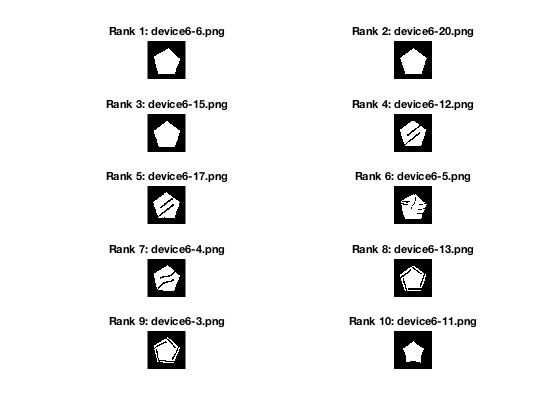

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_5 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

figure % plot the ranked 10 images according to VisualRank function
for i = 1:10
   subplot(5,2,i)
   Img_5 = imread(sprintf("./MPEG7/%s", C4(i,1)))
   imshow(Img_5)
   title(sprintf("Rank %d: %s",i ,C4(i,1)))
end

% assigning values to x and y axes to form a bar plot
x = categorical({'device6-6','device6-20', 'device6-12', 'device6-15', 'device6-17', 'device6-5', 'device6-4', 'device6-13', 'device6-3', 'device6-11'}) 

x = 1×10 categorical array
     device6-6      device6-20      device6-12      device6-15      device6-17      device6-5      device6-4      device6-13      device6-3      device6-11 


x = reordercats(x,{'device6-6','device6-20', 'device6-12', 'device6-15', 'device6-17', 'device6-5', 'device6-4', 'device6-13', 'device6-3', 'device6-11'}) % preserve the order of of categories

x = 1×10 categorical array
     device6-6      device6-20      device6-12      device6-15      device6-17      device6-5      device6-4      device6-13      device6-3      device6-11 


y = val(1:10) % assign magnitude of rank for each element of vector rt to y-axis

y =     0.1063    0.1058    0.1058    0.1006    0.1004    0.1002    0.0987    0.0972    0.0962    0.0888


figure % bar plot the ten images according to VisualRank
     b = bar(x,y, 'm', 'EdgeColor', 'c', 'LineWidth', 1)

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [1 0 1]
    EdgeColor: [0 1 1]
    BaseValue: 0
        XData: [device6-6    device6-20    device6-12    device6-15    device6-17    device6-5    device6-4    device6-13    device6-3    device6-11]
        YData: [0.1063 0.1058 0.1058 0.1006 0.1004 0.1002 0.0987 0.0972 0.0962 0.0888]

  Show all properties


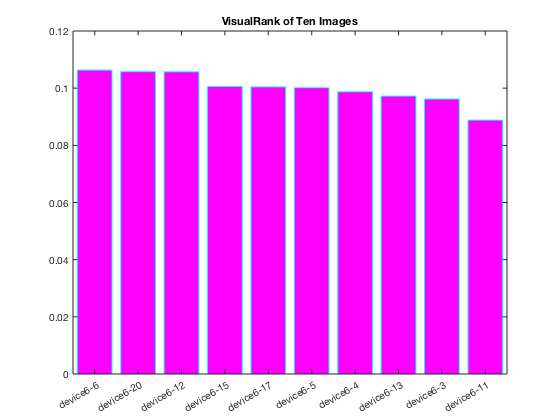

     title('VisualRank of Ten Images')

## Optional: VisualRank function

**The VisualRank function is written in separate file visualrank.m. Task 2 and 3c can be performed through this function.**

**2. Rank the 20 heart-shaped images (indices 81 through 100) using VisualRank.**

**a. Make a smaller 20x20 adjacency matrix by indexing the necessary rows andcolumns of the full adjacency matrix from above. **

**b. Form the corresponding visual hyperlink matrix and find the VisualRank vector for all 20 heart images. **

load sim.mat; %load the matrix into MatLab environment
A = S; % define adjacency matrix A
As = A(81:100,81:100); % create a smaller adjacency matrix As
Heart = visualrank(As); % apply visualrank function to all of the 20 heart images

H =          0    0.0494    0.0563    0.0514    0.0553    0.0579    0.0539    0.0496    0.0554    0.0524    0.0543    0.0503    0.0459    0.0563    0.0552    0.0464    0.0559    0.0547    0.0507    0.0486
    0.0559         0    0.0538    0.0515    0.0528    0.0558    0.0555    0.0510    0.0575    0.0494    0.0527    0.0492    0.0545    0.0551    0.0540    0.0452    0.0536    0.0540    0.0525    0.0460
    0.0578    0.0488         0    0.0522    0.0549    0.0576    0.0534    0.0488    0.0549    0.0556    0.0538    0.0503    0.0452    0.0559    0.0548    0.0467    0.0555    0.0542    0.0501    0.0494
    0.0568    0.0503    0.0562         0    0.0537    0.0568    0.0524    0.0476    0.0539    0.0524    0.0564    0.0492    0.0491    0.0550    0.0538    0.0470    0.0558    0.0547    0.0510    0.0477
    0.0578    0.0487    0.0558    0.0508         0    0.0575    0.0532    0.0515    0.0547    0.0576    0.0536    0.0499    0.0450    0.0558    0.0547    0.0459    0.0553    0.0541    0.0503  

nmax = 50

r =     0.0075    0.0495    0.0554    0.0512    0.0545    0.0568    0.0533    0.0496    0.0546    0.0520    0.0537    0.0503    0.0466    0.0554    0.0544    0.0470    0.0550    0.0540    0.0506    0.0488


output =     0.0556    0.0480    0.0520    0.0488    0.0512    0.0530    0.0504    0.0472    0.0513    0.0492    0.0509    0.0487    0.0453    0.0523    0.0514    0.0456    0.0520    0.0513    0.0489    0.0469


r =     0.0556    0.0480    0.0520    0.0488    0.0512    0.0530    0.0504    0.0472    0.0513    0.0492    0.0509    0.0487    0.0453    0.0523    0.0514    0.0456    0.0520    0.0513    0.0489    0.0469


output =     0.0532    0.0480    0.0522    0.0490    0.0514    0.0532    0.0506    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0532    0.0480    0.0522    0.0490    0.0514    0.0532    0.0506    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0521    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0521    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


r =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


output =     0.0533    0.0480    0.0521    0.0489    0.0514    0.0532    0.0505    0.0473    0.0515    0.0493    0.0511    0.0488    0.0453    0.0525    0.0516    0.0456    0.0522    0.0514    0.0489    0.0470


filenames_s = filenames(81:100); % extract filenames for the corresponding images
[val2,rank2] = sort(Heart,'descend') % sort and rank elements of r vector in descending order

val2 =     0.0533    0.0532    0.0525    0.0522    0.0521    0.0516    0.0515    0.0514    0.0514    0.0511    0.0505    0.0493    0.0489    0.0489    0.0488    0.0480    0.0473    0.0470    0.0456    0.0453


rank2 =      1     6    14    17     3    15     9    18     5    11     7    10     4    19    12     2     8    20    16    13


**c. Given this ranking, which heart-shaped image is most representative of the group of heart-shaped images? Display this image. **

most = rank2(1) % most representative heart-shaped image according to VisualRank function

most = 1

disp('The most representative heart shaped image is: '), filenames_s(most,1) % display this image

The most representative heart shaped image is: 


ans = 1×1 cell array
    {'Heart-1.png'}


C1 = convertCharsToStrings(filenames_s); % convert characters to strings
figure; % plot the most representative image
img_6 = imread(sprintf("./MPEG7/%s", C1(most,1)));
imshow(img_6);
title(sprintf("The highest ranked image is %s", C1(most,1)));

**d. Similarly, which heart-shaped image is the least heart-shaped (according toVisualRank)? Also display this image. **

least = rank2(20) % least heart-shaped image according to VisualRank 

least = 13

disp('The least heart shaped image is: '), filenames_s(least,1) % display this image

The least heart shaped image is: 


ans = 1×1 cell array
    {'Heart-20.png'}


figure; % plot the least heart-shaped image
img_3 = imread(sprintf("./MPEG7/%s", C1(least,1)))

img_3 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

imshow(img_3);
title(sprintf("The least heart shaped image is %s", C1(least,1)));

**3 c. Finally, rank these 10 nearest images using VisualRank and display them on a figure in their ranked order. This is the final search result. **

load sim.mat % load the matrix into MatLab environment
A = S % define adjacency matrix A

A =     1.0000    0.9585    0.8079    0.7192    0.9924    0.8633    0.7679    0.8492    0.6913    0.5417    0.6161    0.9568    0.6388    0.9847    0.9811    0.9737    0.9839    0.6893    0.6435    0.9646    0.1448    0.1311    0.2043    0.1586    0.1798    0.1231    0.1006    0.0975    0.1672    0.1261
    0.9585    1.0000    0.7748    0.6916    0.9530    0.8842    0.7857    0.8392    0.6577    0.5257    0.5859    0.9157    0.6222    0.9438    0.9412    0.9332    0.9425    0.6554    0.6108    0.9243    0.1702    0.1543    0.2242    0.1822    0.2067    0.1478    0.1036    0.1038    0.1907    0.1442
    0.8079    0.7748    1.0000    0.8702    0.8082    0.7393    0.6907    0.7165    0.5592    0.7032    0.4553    0.8321    0.6659    0.7920    0.8176    0.7957    0.7942    0.5045    0.5675    0.7663    0.1548    0.1446    0.2016    0.1453    0.1876    0.1346    0.1355    0.0979    0.1513    0.1711
    0.7192    0.6916    0.8702    1.0000    0.7198    0.6704    0.6312    0.6448    0.4778   

At = A([643 644 645 647 649 653 654 655 656 657],[643 644 645 647 649 653 654 655 656 657]); % create a small adjacency matrix for those 10 images
Device = visualrank(At); % apply visualrank function to all 10  images

H =          0    0.1004    0.1184    0.1179    0.1002    0.1178    0.1170    0.1009    0.1096    0.1179
    0.0868         0    0.1077    0.1161    0.1358    0.1159    0.1015    0.1137    0.1064    0.1161
    0.1065    0.1121         0    0.1129    0.1102    0.1130    0.1187    0.1070    0.1057    0.1139
    0.0961    0.1096    0.1024         0    0.1098    0.1302    0.1007    0.1086    0.1169    0.1258
    0.0867    0.1361    0.1060    0.1165         0    0.1163    0.1013    0.1137    0.1069    0.1164
    0.0960    0.1094    0.1024    0.1302    0.1096         0    0.1007    0.1085    0.1172    0.1260
    0.1065    0.1070    0.1202    0.1125    0.1066    0.1125         0    0.1138    0.1063    0.1148
    0.0891    0.1162    0.1051    0.1176    0.1160    0.1175    0.1103         0    0.1093    0.1189
    0.0951    0.1069    0.1020    0.1244    0.1072    0.1248    0.1013    0.1074         0    0.1308
    0.0956    0.1089    0.1027    0.1250    0.1091    0.1253    0.1022    0.1091    0.1

nmax = 50

r =     0.0150    0.1004    0.1156    0.1152    0.1002    0.1151    0.1144    0.1008    0.1082    0.1152


output =     0.0952    0.1012    0.0949    0.1049    0.1010    0.1049    0.0939    0.0991    0.0995    0.1055


r =     0.0952    0.1012    0.0949    0.1049    0.1010    0.1049    0.0939    0.0991    0.0995    0.1055


output =     0.0883    0.1005    0.0975    0.1059    0.1004    0.1059    0.0964    0.0987    0.1002    0.1064


r =     0.0883    0.1005    0.0975    0.1059    0.1004    0.1059    0.0964    0.0987    0.1002    0.1064


output =     0.0889    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0889    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


r =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


output =     0.0888    0.1006    0.0972    0.1058    0.1004    0.1058    0.0962    0.0987    0.1002    0.1063


filanames_t = filenames([643 644 645 647 649 653 654 655 656 657],1); % extract the filenames for the corresponding images
[val3,rank3] = sort(Device,'descend') % sort and rank elements of r vector in descending order

val3 =     0.1063    0.1058    0.1058    0.1006    0.1004    0.1002    0.0987    0.0972    0.0962    0.0888


rank3 =     10     6     4     2     5     9     8     3     7     1


Ten_img = filanames_t (rank3,1) % ranked filenames according to the ranked images

Ten_img = 10×1 cell array
    {'device6-6.png' }
    {'device6-20.png'}
    {'device6-15.png'}
    {'device6-12.png'}
    {'device6-17.png'}
    {'device6-5.png' }
    {'device6-4.png' }
    {'device6-13.png'}
    {'device6-3.png' }
    {'device6-11.png'}


C6 = convertCharsToStrings(Ten_img) % convert character to string

C6 = 10×1 string array
    "device6-6.png"
    "device6-20.png"
    "device6-15.png"
    "device6-12.png"
    "device6-17.png"
    "device6-5.png"
    "device6-4.png"
    "device6-13.png"
    "device6-3.png"
    "device6-11.png"


Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Img_8 = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  


figure % plot the ranked 10 images according to VisualRank function
for i = 1:10
   subplot(5,2,i)
   Img_8 = imread(sprintf("./MPEG7/%s", C6(i,1)))
   imshow(Img_8)
   title(sprintf("Rank %d: %s",i ,C6(i,1)))
end

% assigning values to x and y axes
x = categorical({'device6-6','device6-20', 'device6-12', 'device6-15', 'device6-17', 'device6-5', 'device6-4', 'device6-13', 'device6-3', 'device6-11'}) 

x = 1×10 categorical array
     device6-6      device6-20      device6-12      device6-15      device6-17      device6-5      device6-4      device6-13      device6-3      device6-11 


x = reordercats(x,{'device6-6','device6-20', 'device6-12', 'device6-15', 'device6-17', 'device6-5', 'device6-4', 'device6-13', 'device6-3', 'device6-11'}); % preserve the order of of categories
y = val3(1:10) % assign magnitude of rank for each element of vector r to y-axis

y =     0.1063    0.1058    0.1058    0.1006    0.1004    0.1002    0.0987    0.0972    0.0962    0.0888


figure; % bar plot the ten images according to VisualRank function
     b = bar(x,y, 'm', 'EdgeColor', 'c', 'LineWidth', 1)

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [1 0 1]
    EdgeColor: [0 1 1]
    BaseValue: 0
        XData: [device6-6    device6-20    device6-12    device6-15    device6-17    device6-5    device6-4    device6-13    device6-3    device6-11]
        YData: [0.1063 0.1058 0.1058 0.1006 0.1004 0.1002 0.0987 0.0972 0.0962 0.0888]

  Show all properties


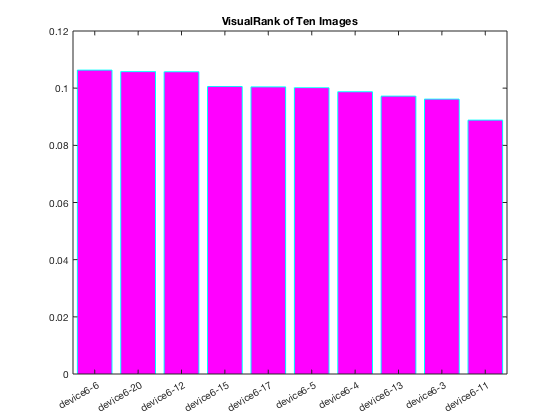

     title('VisualRank of Ten Images')